# Fourier Edge Math

## Setting up the workspace

clear;
%addpath( '/Volumes/GoogleDrive/My Drive/Code/MATLAB Code/Useful Code');
load('ImpVariables.mat');

## Definition of time and variables

t_res = 0.001*nan; % temporal resolution
f_res = 1/t_res;
f_rep = 10*meg; %10MHz repetition rate
t_rep = 1/f_rep; %period of the repetition

## Positive and Negative Time Setting - SLIGHTLY Asymmetric! To enforce periodicity

timeN = -t_rep/2:t_res:-t_res;          % From negative start just to before 0
time0P = 0:t_res:t_rep/2-t_res;         % From 0 to maximum just before maximum positive
time = [timeN time0P];                  % Combine two

tLength = length(time);                  %Should be divisible by 2!! for halves of response
n = tLength

n = 100000

    

fP = f_res*(0:(tLength/2))/tLength;         % Since FT symmetric now
f  = f_res*(-tLength/2:tLength/2)/tLength;        % Full FT frequency domain


## Functions to mess with

% Simple gaussian
gaussCoef = 5e15;
Gaussian = exp(-gaussCoef*time.^2);

% Sinusoid
nPer = 50; % number of periods
cosFn = cos(2*nPer*pi*f_rep*time);

% Rescaled RC time train
rcCoef = 1e-9;
RC_EdgeN = 1-exp(-((timeN-timeN(1))/rcCoef));
RC_Edge0P  = RC_EdgeN(end)*exp(-time0P/rcCoef);
RC_Edge = [RC_EdgeN RC_Edge0P];
RC_Edge = rescale(RC_Edge,-0.5, 0.5);

% Gaussian edge pulse
gEdgeCoef = 10e15;
gEdgeN = exp(-gEdgeCoef*timeN.^2);
gEdge0P = (gEdgeN(1)+1-exp(-gEdgeCoef*timeN.^2));
gEdge = [gEdgeN gEdge0P];

## Select Function and plot it

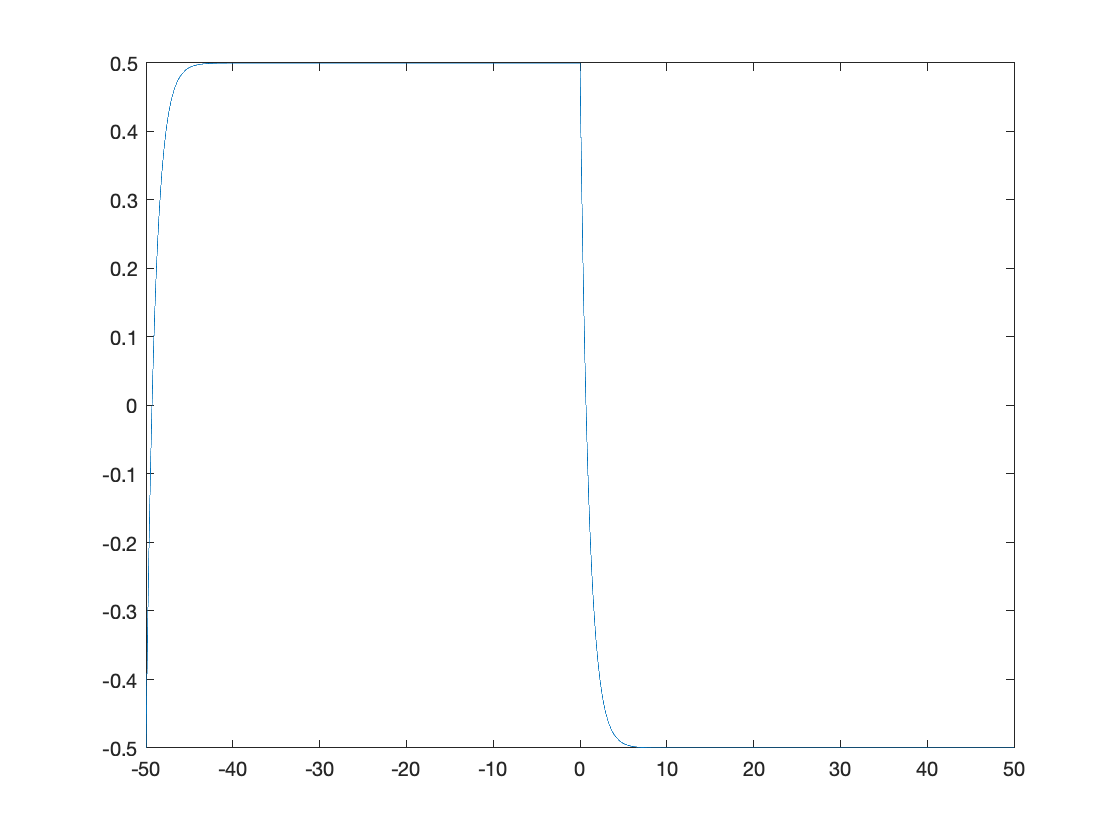

%fn2plot selects the array in the time base we want to plot
fn2plot =RC_Edge;
plot(time/nan,fn2plot);

## Fourier Transform

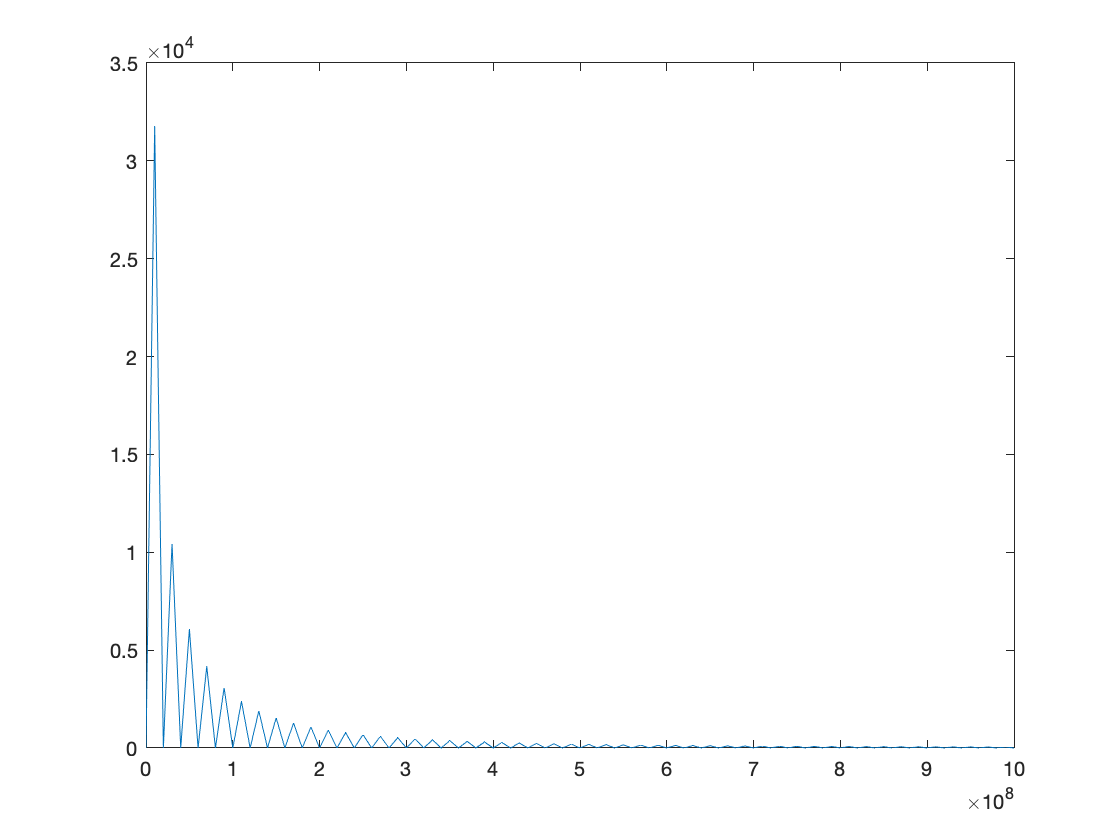

fn_FFT = fft(fn2plot,n);
fn_FFT_P = fn_FFT(1:n/2+1);
plot(fP,abs(fn_FFT_P))
fmin = 0;
fmax = 1*gig;
xlim([fmin, fmax]);

G_FFT = fft(Gaussian, n);
P = abs(G_FFT/n);


## Inverse Fourier Transform

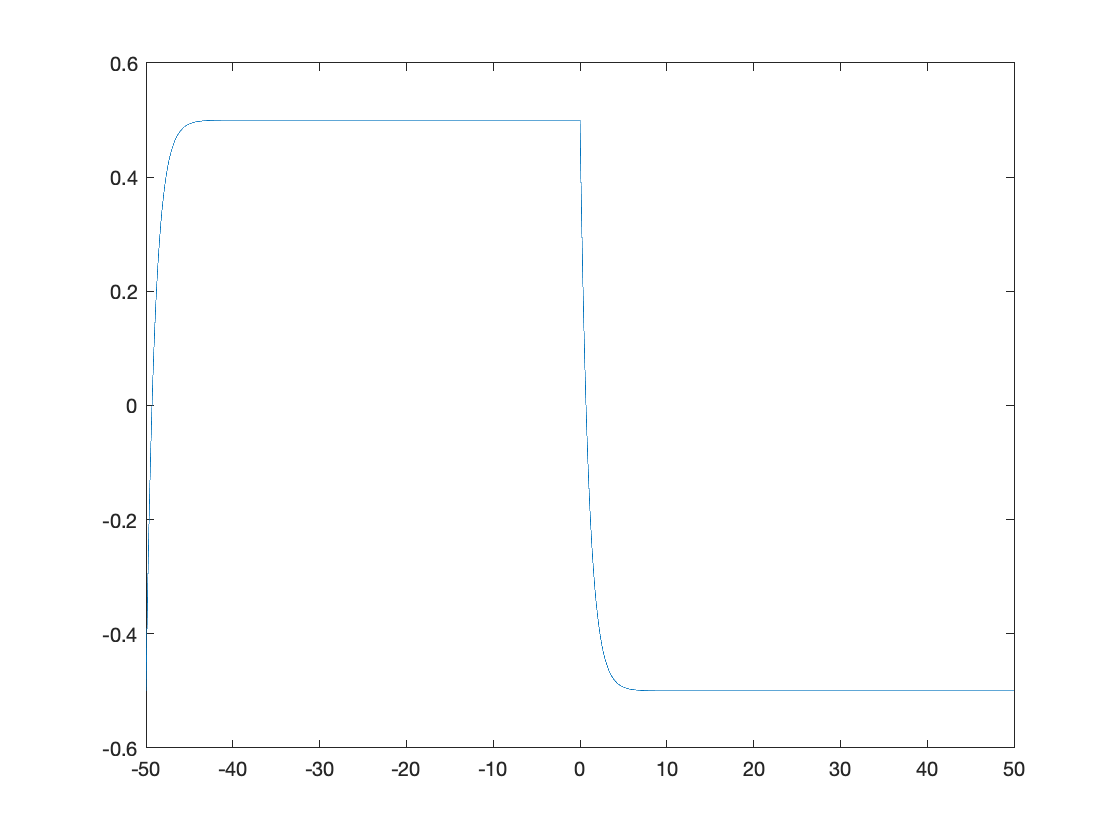

invFnFFT = ifft(fn_FFT);
plot(time/nan,invFnFFT);

## Plotting Settings

% x0=0;
% y0=0;
% width=1000;
% height=750;
% 
% set(gcf,'position',[x0,y0,width,height])
% set(gcf,'DefaultLineLineWidth',3)
% set(gca,'FontSize',25)
% grid on;
% grid minor;